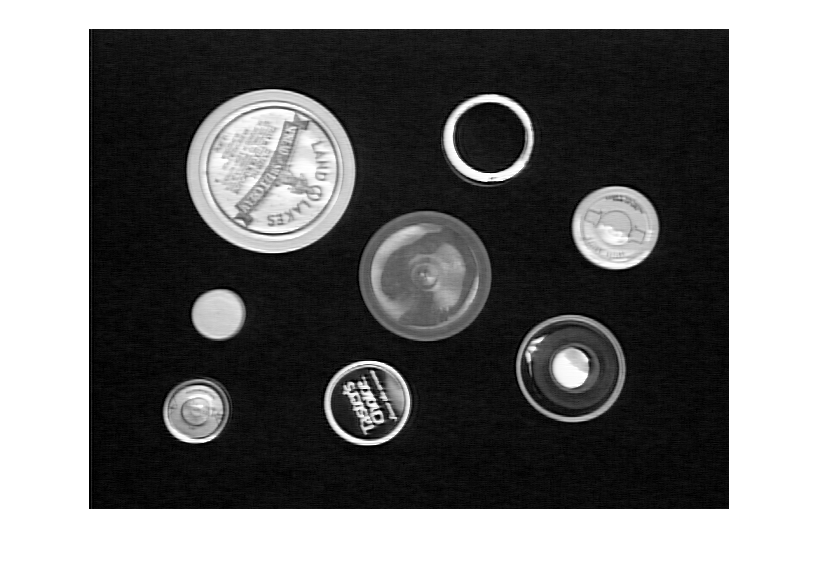

        % PART 2
% Read the original image
image = imread('circles1.gif');
% Define the size and variance of the Gaussian smoothing kernel
K = 7; % Filter size
sigma = 3; % Variance
% Compute the Gaussian kernel
kernel = zeros(K, K);
center = floor(K / 2);
for i = 1:K
    for j = 1:K
        x = i - center;
        y = j - center;
        kernel(i, j) = (1 / (2 * pi * sigma^2)) * exp(-((x^2 + y^2) / (2 * sigma^2)));
    end
end
% Normalize the kernel
kernel = kernel / sum(kernel(:));
% Get the size of the image
[m, n] = size(image);
% Initialize the smoothed image
smoothed_image = zeros(m, n);
% Pad the image with zeros
padded_image = padarray(image, [center center]);
% Apply the kernel to the image
for i = 1:m
    for j = 1:n
        % Extract the local region around the pixel
        region = padded_image(i:i+K-1, j:j+K-1);
        
        % Element-wise multiplication between the kernel and the region
        result = kernel .* double(region);
        
        % Sum the products and assign it to the corresponding pixel
        smoothed_image(i, j) = sum(result(:));
    end
end
imshow(image);

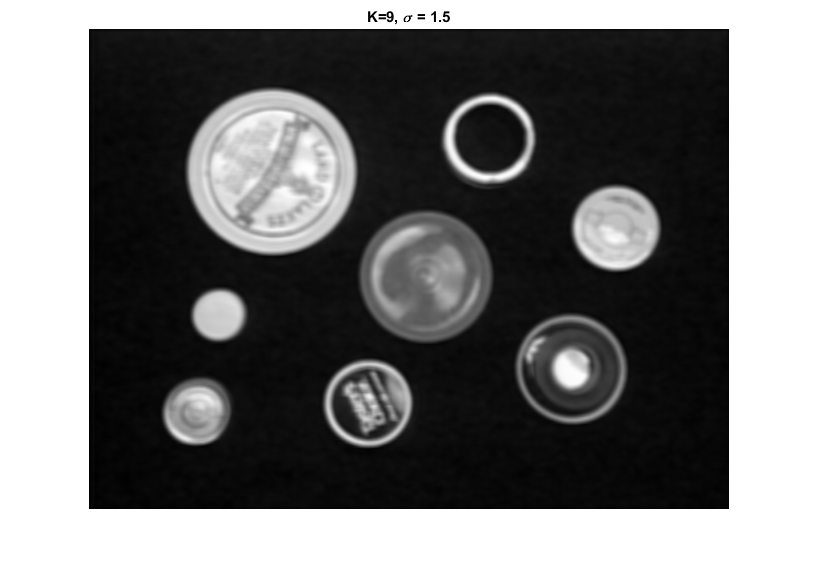

imshow(smoothed_image, []);
title("K=9, \sigma = 1.5")

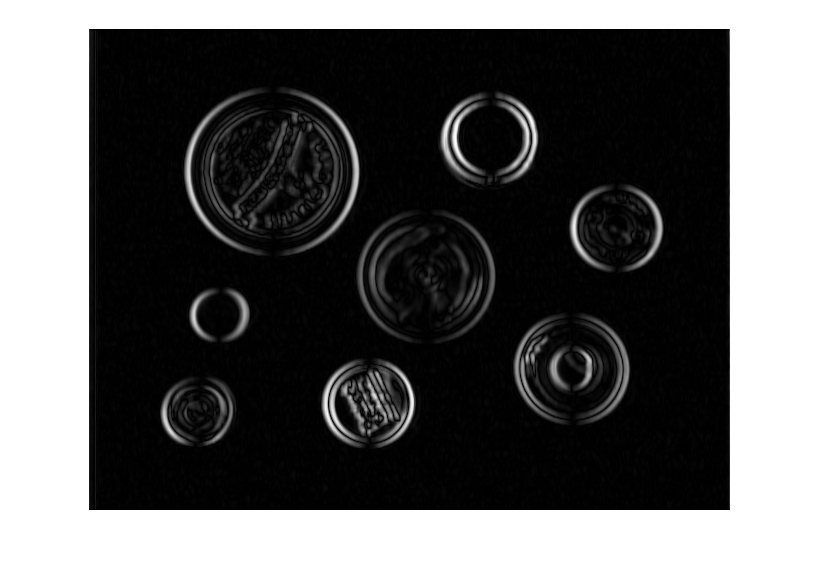


        % PART 3
% Read the original image
image = imread('circles1.gif');

% Pad the image with zeros
padded_image = padarray(smoothed_image, [1 1]);

% Compute the gradients using finite differences
grad_x = double(padded_image(2:end, 1:end-1)) - double(padded_image(2:end, 2:end)); % Change in x direction
grad_y = double(padded_image(1:end-1, 2:end)) - double(padded_image(2:end, 2:end)); % Change in y direction

% Compute the overall magnitude of the combined gradients
grad_mag = abs(grad_x) + abs(grad_y);

% Display the absolute change in x direction
imshow(abs(grad_x), []);

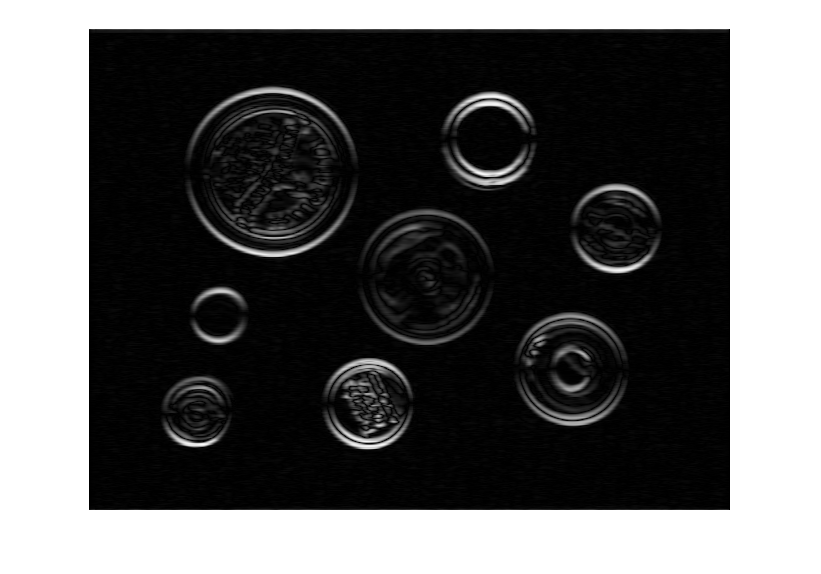


imshow(abs(grad_y), []);

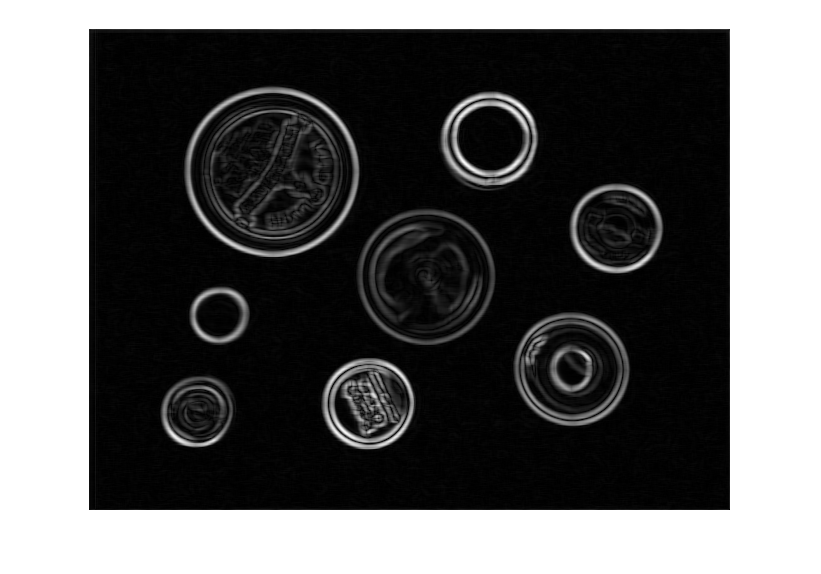

imshow(abs(grad_mag), []);

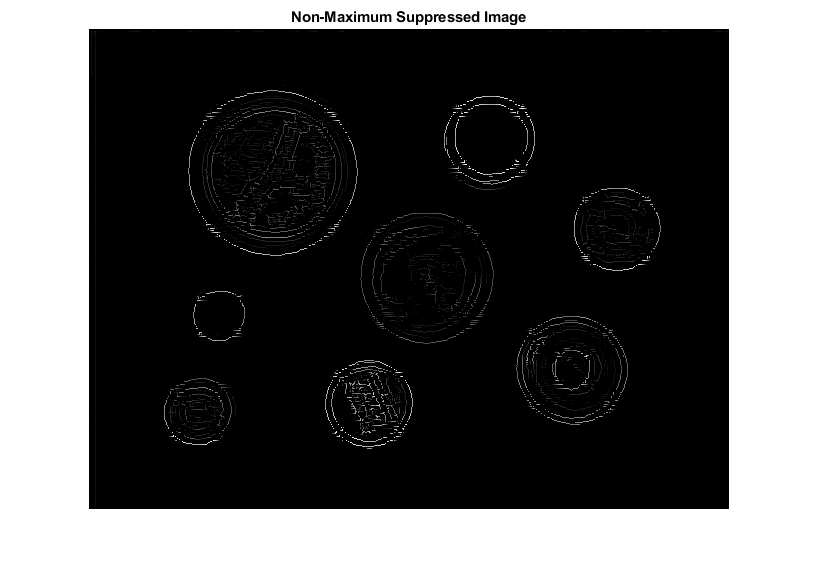


grad_angle = atan2(grad_y, grad_x);

% Threshold for non-maximum suppression
threshold = 0.05 * max(grad_mag(:));

% Perform non-maximum suppression
[m, n] = size(image);
suppressed_image = zeros(m, n);
for i = 2:m-1
    for j = 2:n-1
        % Get the gradient magnitude of the current pixel
        current_mag = grad_mag(i, j);
        
        % Get the angle of the gradient for the current pixel
        current_angle = grad_angle(i, j);
        
        % Determine the nearest locations in the direction and opposite direction
        if (current_angle >= -pi/8 && current_angle <= pi/8) || (current_angle >= 7*pi/8 || current_angle <= -7*pi/8)
            neighbor1 = grad_mag(i, j+1);
            neighbor2 = grad_mag(i, j-1);
        elseif (current_angle > pi/8 && current_angle < 3*pi/8) || (current_angle < -5*pi/8 && current_angle > -7*pi/8)
            neighbor1 = grad_mag(i-1, j+1);
            neighbor2 = grad_mag(i+1, j-1);
        elseif (current_angle >= 3*pi/8 && current_angle <= 5*pi/8) || (current_angle >= -5*pi/8 && current_angle <= -3*pi/8)
            neighbor1 = grad_mag(i-1, j);
            neighbor2 = grad_mag(i+1, j);
        else
            neighbor1 = grad_mag(i-1, j-1);
            neighbor2 = grad_mag(i+1, j+1);
        end
        
        % Perform non-maximum suppression
        if current_mag >= neighbor1 && current_mag >= neighbor2 && current_mag >= threshold
            suppressed_image(i, j) = current_mag;
        end
    end
end

% Display the suppressed image
imshow(suppressed_image, []);
title('Non-Maximum Suppressed Image');